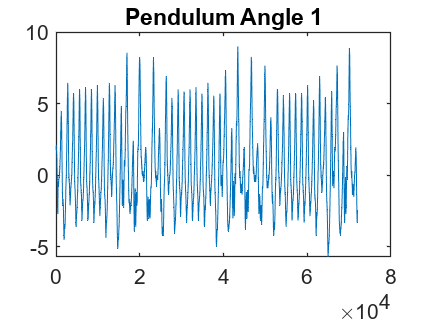

clear
close all
load("LinkedPendulum_OneSineInput_InputPendulum1.mat");

x1 = pendulum_angle;
y1 = rotor_angle;

load("Edukit_Step Resp Rotor Angle __2pend_one_sine_input1_.mat")
x2 = pendulum_angle;
y2 = rotor_angle;

plot(x1);
title("Pendulum Angle 1")

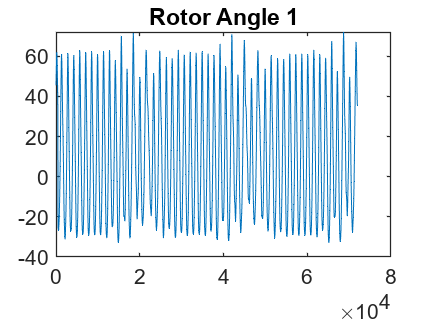

plot(y1);
title("Rotor Angle 1")

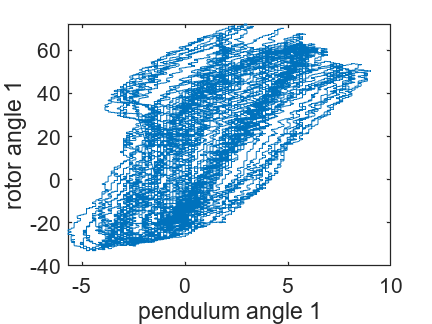

plot(x1,y1)
xlabel("pendulum angle 1")
ylabel("rotor angle 1")

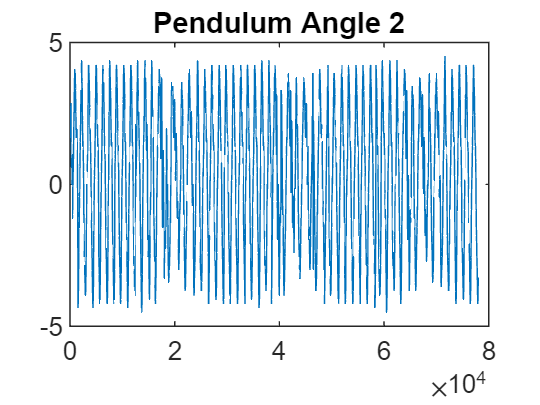


plot(x2);
title("Pendulum Angle 2")

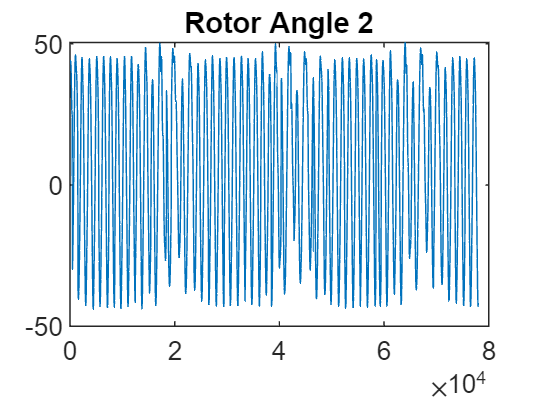

plot(y2);
title("Rotor Angle 2")

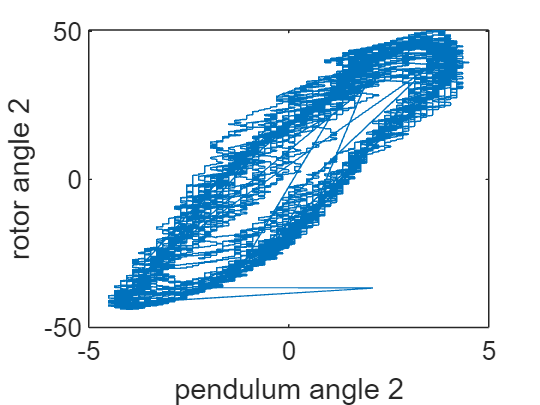

plot(x2,y2)
xlabel("pendulum angle 2")
ylabel("rotor angle 2")

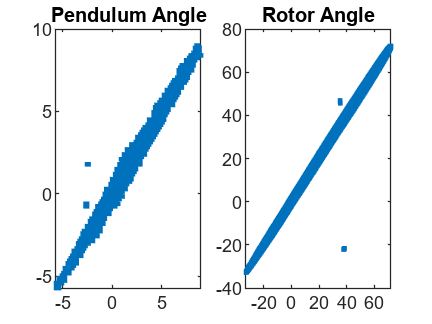

for i=1:1000
    subplot(1,2,1)
    plot(x1,[x1(i+1:end) x1(1:i)],'.');
    title("Pendulum Angle")
    subplot(1,2,2)
    plot(y1,[y1(i+1:end) y1(1:i)],'.');
    title("Rotor Angle")
    if mod(i,10)==0
    pause
    end

end

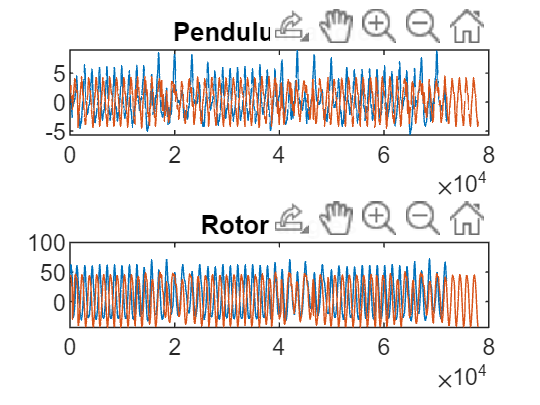

subplot(2,1,1)
plot(x1)
hold on
plot(x2)
title('Pendulum angles')
subplot(2,1,2)
plot(y1)
hold on
plot(y2)
title('Rotor angles')


% plot(x1, x2);
% title("Plot x1 with respect to x2");
% xlabel("pendulum angle 1")
% ylabel("pendulum angle 2")

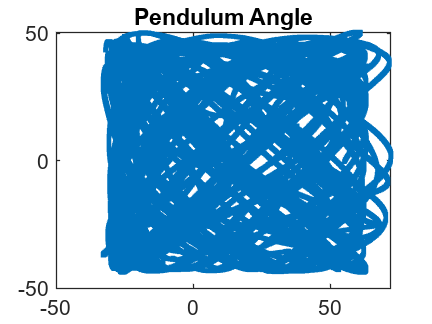

% x1 ha dimensione 72000
% x2 ha dimensione 78000

y2 = y2(1, 1:72000);

for i=1:1000
%     subplot(1,2,1)
    plot(y1,[y2(i+1:end) y2(1:i)],'.');
    title("Pendulum Angle")
%     subplot(1,2,2)
%     plot(y1,[y2(i+1:end) y2(1:i)],'.');
%     title("Rotor Angle")
    if mod(i,10)==0
    pause
    end

end